summary(Training)

Variables:

    Pregnancies: 2460×1 double

        Values:

            Min           0   
            Median        3   
            Max          17   

    Glucose: 2460×1 double

        Values:

            Min           0   
            Median      117   
            Max         197   

    BloodPressure: 2460×1 double

        Values:

            Min           0   
            Median       70   
            Max         122   

    SkinThickness: 2460×1 double

        Values:

            Min           0   
            Median       23   
            Max          63   

    Insulin: 2460×1 double

        Values:

            Min           0   
            Median       36   
            Max         846   

    BMI: 2460×1 double

        Values:

            Min            0  
            Median      32.1  
            Max         67.1  

    DiabetesPedigreeFunction

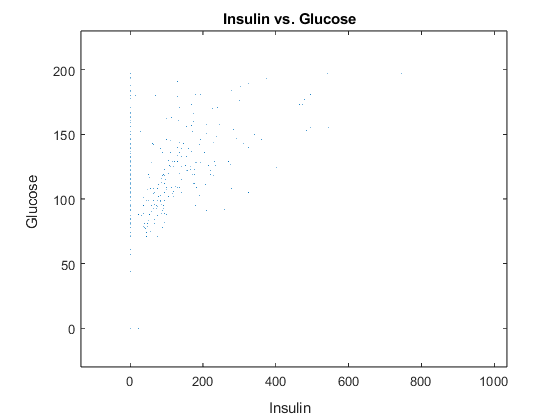

% Create plotmatrix of Training.Insulin and Training.Glucose
[S,AX,BigAx,H,HAx] = plotmatrix(Training.Insulin,Training.Glucose);

% Add xlabel, ylabel, and title
xlabel('Insulin')
ylabel('Glucose')
title('Insulin vs. Glucose')

testAnswers = Testing.Outcome;
testData = removevars(Testing,"Outcome")

testData = 308×8 table
    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___

         9           120           72               22             56      20.8             0.733              48 
         1            71           62                0              0      21.8             0.416              26 
         8            74           70               40             49      35.3             0.705              39 
         5            88           78               30              0      27.6             0.258              37 
        10    

trainedModel

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Age'  'BMI'  'BloodPressure'  'DiabetesPedigreeFunction'  'Glucose'  'Insulin'  'Pregnancies'  'SkinThickness'}
    ClassificationKNN: [1×1 ClassificationKNN]
                About: 'This struct is a trained model exported from Classification Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


make_prediction = trainedModel.ClassificationKNN

make_prediction =   ClassificationKNN
           PredictorNames: {'Pregnancies'  'Glucose'  'BloodPressure'  'SkinThickness'  'Insulin'  'BMI'  'DiabetesPedigreeFunction'  'Age'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 2460
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


predictdiabetic= trainedModel.predictFcn(testData)

predictdiabetic =      0
     0
     0
     0
     1
     0
     0
     0
     0
     1


table(predictdiabetic)

ans = 308×1 table
    predictdiabetic
    _______________

           0       
           0       
           0       
           0       
           1       
           0       
           0       
           0       
           0       
           1       
           1       
           1       
           0       
           1       
           0       
           0       


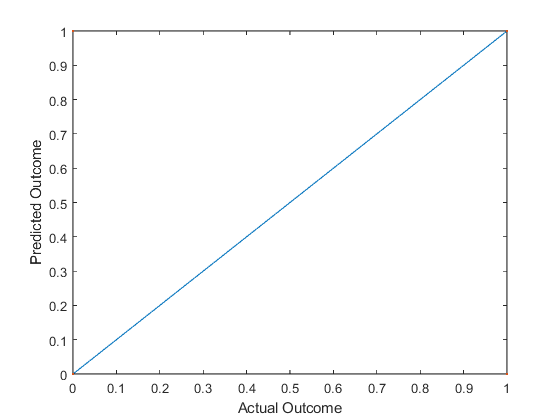

plot(testAnswers, testAnswers);
hold on
plot(testAnswers,predictdiabetic,".");
hold off
xlabel('Actual Outcome');
ylabel('Predicted Outcome');

model_diabetes= trainedModel;
save model_diabeties.mat;

diabetesID = (1:length(predictdiabetic))';
testData = addvars(testData,diabetesID,'Before', 'Pregnancies')

testData = 308×10 table
    diabetiesID    diabetesID    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age
    ___________    __________    ___________    _______    _____________    _____________    _______    ____    ________________________    ___

         1              1             9           120           72               22             56      20.8             0.733              48 
         2              2             1            71           62                0              0      21.8             0.416              26 
         3              3             8            74      

testResults = table(testData.diabetesID,predictdiabetic,'VariableNames',{'diabetes_id',...
    'predicted_outcome'})

testResults = 308×2 table
    diabetes_id    predicted_outcome
    ___________    _________________

         1                 0        
         2                 0        
         3                 0        
         4                 0        
         5                 1        
         6                 0        
         7                 0        
         8                 0        
         9                 0        
        10                 1        
        11                 1        
        12                 1        
        13                 0        
        14                 1        
        15                 0        
        16                 0        


writetable(testResults,'testResults_diabetes.csv');